clc;  clear;
dx=.1;
x = -2*pi:dx:2*pi;
y1 = sinc(x);
cte1 = .6;
cte2 = -.1;
fcte1= x/10+.5;
y2 = cte2*(y1./y1);
y2 = 0*x + cte2;
% y2 = zeros(length(x)) + cte2;
plot(x,y1,'bo','LineWidth',3);   grid;
hold on


graficar círculos negros entre las líneas roja y verde

Una forma: graficar elemento a elemento

% for i = 1:length(x)
%     if y1(i) > cte2 & y1(i) < cte1
%         plot(x(i),y1(i),'ko','LineWidth',3);
%     end
% end

Otra forma: Creando nuevo arreglo de datos

y3 = (y1>cte2 & y1<fcte1);
y4 = y1(y3);
x4 = x(y3)

x4 =    -5.4832   -5.3832   -5.2832   -5.1832   -5.0832   -4.2832   -4.1832   -4.0832   -3.9832   -3.8832   -3.7832   -3.6832   -3.5832   -3.4832   -3.3832   -3.2832   -3.1832   -3.0832   -2.9832   -2.8832   -2.7832   -2.6832   -2.5832   -2.4832   -2.3832   -2.2832   -2.1832   -2.0832   -1.9832   -1.8832   -1.0832   -0.9832   -0.8832   -0.7832   -0.6832    0.6168    0.7168    0.8168    0.9168    1.0168    1.8168    1.9168    2.0168    2.1168    2.2168    2.3168    2.4168    2.5168    2.6168    2.7168


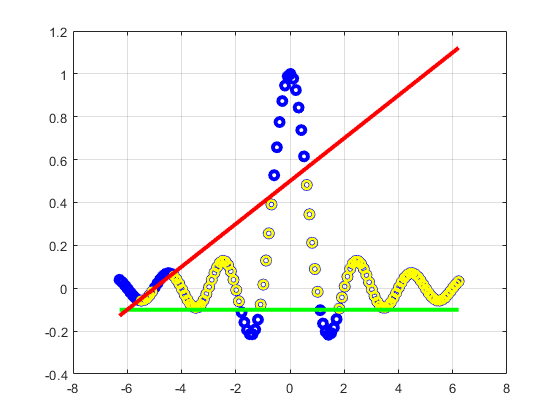

plot(x4,y4,'yo','lineWidth',2)


plot(x,y2,'g','lineWidth',3)
% line([x(1),x(end)],[cte1,cte1], ...
%     'linewidth',3,'color',[1,0,0]);
plot(x,fcte1,'r','lineWidth',3)

hold off